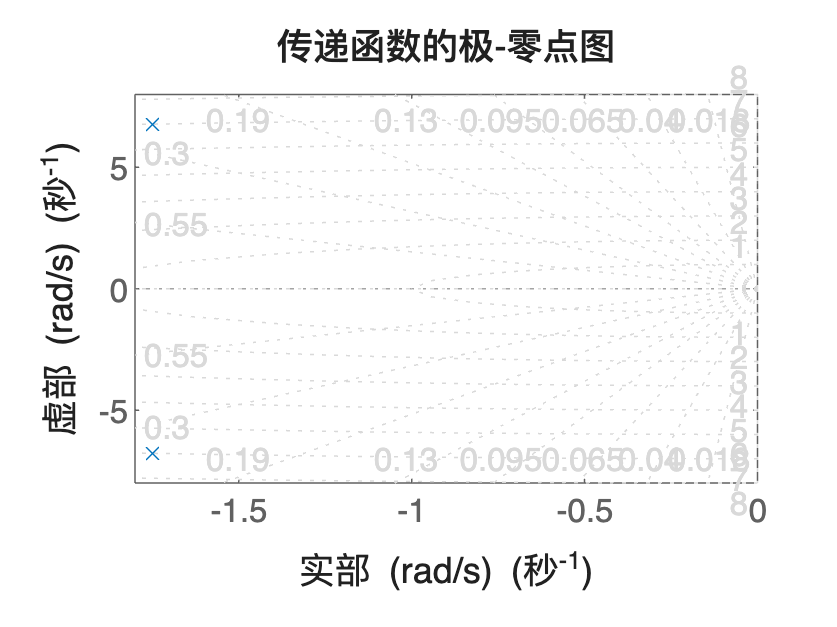

% 参数定义
g = 9.81; % m/s^2, 重力加速度
m = 5; % kg, 质量
l = 0.4; % m, 长度
c = 0.7; % Nm/rad, 阻尼系数
I = m * (l/2)^2; % kg·m², 惯量矩

% 计算动态特性
wn = sqrt(m * g * l / (2 * I)); % rad/s, 自然频率
xi = c / (2 * I * wn); % 阻尼比

% 定义传递函数
% 传递函数形式: sys = 1/I / (s^2 + 2*xi*wn*s + wn^2)
num = 1 / I; % 分子
den = [1, 2*xi*wn, wn^2]; % 分母
sys = tf(num, den); % 创建传递函数对象

% 绘制极-零点图
figure; % 创建新图形窗口
pzplot(sys); % 绘制极-零点图
grid on; % 添加网格
title('传递函数的极-零点图'); % 设置标题
xlabel('实部 (rad/s)'); % X轴标签
ylabel('虚部 (rad/s)'); % Y轴标签


% 可选：调整图形属性
set(findobj(gca, 'Type', 'Line'), 'MarkerSize', 10, 'LineWidth', 2); % 增大标记尺寸和线宽